# Latent to EEG

% Generates 32-channel EEG-like data from 3 latent variables using a frozen MLP.
clear; clc; close all;

## Parameters

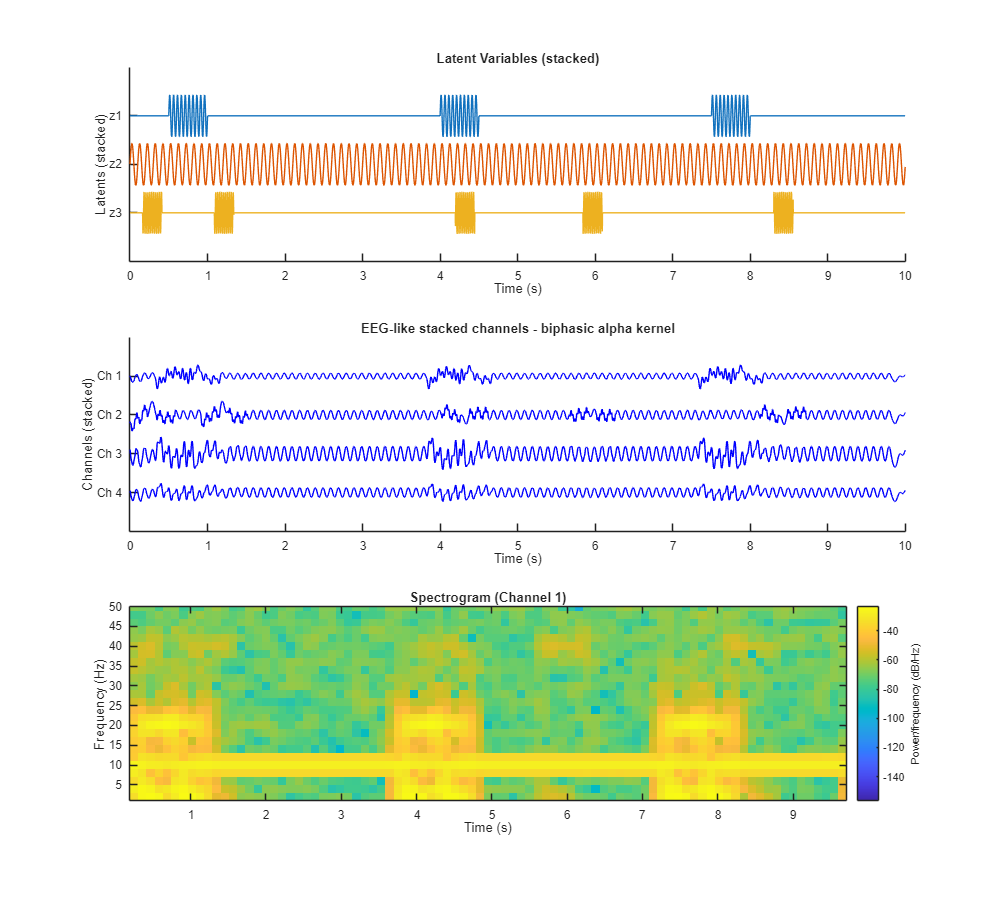

fs = 512;                 % Sampling frequency (Hz)
duration = 10;            % Duration (seconds)
t = 0:1/fs:duration-1/fs; % Time vector
num_channels = 32;
num_latent = 3;

%% Define latent variables

% Latent 1: transient beta bursts (12-30 Hz every 3.5 s for 0.5 s)
beta_freq = 20; % central frequency
z1 = zeros(size(t));
burst_times = 0.5:3.5:duration;
for bt = burst_times
    idx = (t >= bt) & (t < bt + 0.5);
    z1(idx) = sin(2*pi*beta_freq*t(idx));
end

% Latent 2: continuous alpha (8-12 Hz)
alpha_freq = 10;
z2 = sin(2*pi*alpha_freq*t);

% Latent 3: occasional gamma (30-50 Hz bursts)
gamma_freq = 40;
z3 = zeros(size(t));
burst_times_gamma = sort(rand(1, round(duration/2))*duration);
for bt = burst_times_gamma
    idx = (t >= bt) & (t < bt + 0.25);
    z3(idx) = sin(2*pi*gamma_freq*t(idx));
end

Z = [z1; z2; z3];

%% Generate EEG-like signal using frozen MLP
eeg = run_latent_to_eeg(Z, fs, num_channels);

%% Plot latent variables
figure('Position',[100 100 1000 900]);

%% Plot latent variables (stacked with offset)
subplot(3,1,1);
hold on;
num_latent = size(Z,1);
offset_lat = 5 * std(Z(:));  % vertical spacing

for i = 1:num_latent
    plot(t, Z(i,:) + (num_latent - i)*offset_lat);
end
hold off;
xlim([0 duration]);
ylim([-offset_lat, num_latent*offset_lat]);
xlabel('Time (s)');
ylabel('Latents (stacked)');
yticks((0:num_latent-1)*offset_lat);
yticklabels(arrayfun(@(c) sprintf('z%d', num_latent - c + 1), 1:num_latent, 'UniformOutput', false));
title('Latent Variables (stacked)');


%% Plot example EEG channels stacked with offset
num_channels_plot = 4;
offset = 5 * std(eeg(:));

subplot(3,1,2);
hold on
for ch = 1:num_channels_plot
    plot(t, eeg(ch,:) + (num_channels_plot - ch)*offset, 'b');
end
hold off
xlim([0 duration]);
ylim([-offset, num_channels_plot*offset]);
xlabel('Time (s)');
ylabel('Channels (stacked)');
yticks((0:num_channels_plot-1)*offset);
yticklabels(arrayfun(@(c) sprintf('Ch %d', num_channels_plot - c + 1), 1:num_channels_plot, 'UniformOutput', false));
title('EEG-like stacked channels - biphasic alpha kernel');

%% Plot full EEG spectrogram
subplot(3,1,3);
spectrogram(eeg(1,:), 256, 200, 256, fs, 'yaxis');
ylim([1 50]);
title('Spectrogram (Channel 1)');
ylabel('Frequency (Hz)');
xlabel('Time (s)');

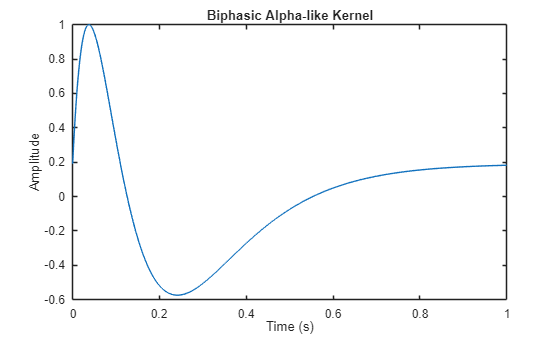

Fs = 512;
dur = 1;
K = biphasic_alpha_kernel(Fs, dur);
% Plot the kernel used for EEG convolution
figure;
% subplot(3,1,3);
plot((0:length(K)-1)/Fs, K);
xlim([0 dur]);
xlabel('Time (s)');
ylabel('Amplitude');
title('Biphasic Alpha-like Kernel');

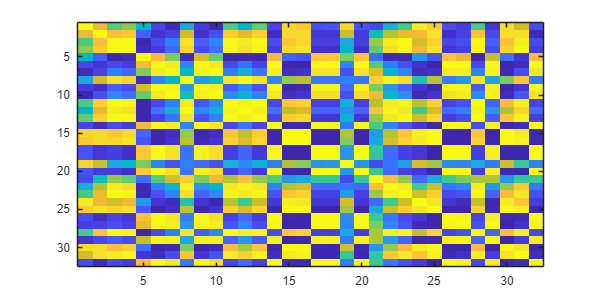

cor = corr(eeg');
figure('Position',[100 100 600 300]);
imagesc(cor);

EEG = eeg_emptyset();
EEG.data   = double(eeg);
EEG.nbchan = size(EEG.data, 1);   % number of "channels" = neurons
EEG.pnts   = size(EEG.data, 2);   % number of time points
EEG.trials = 1;                   % continuous data
EEG.srate  = fs;                 % arbitrary sample rate (adjust if needed)
EEG.xmin   = 0;

%% Assign channel locations (example for 32-channel cap)
% Load your real EEG dataset
EEG_real = pop_loadset('filename', 'binepochs filtered ICArej BLAAvgBOS2.set', ...
                       'filepath', 'G:\My Drive\Data\New Data\EEG epoched\BLA\');

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...



% Copy channel location info to your simulated EEG
EEG.chanlocs = EEG_real.chanlocs;
EEG.times = (0:EEG.pnts-1) / EEG.srate * 1000; % in milliseconds
EEG = eeg_checkset(EEG);

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



%% Define the time windows for topographic snapshots
win_length = 1;   % seconds
interval = 3.5;   % seconds between intervals
n_maps = 3;       % 10 seconds / 3.5 ≈ 3 intervals

map_times = (0:interval:(n_maps-1)*interval) + win_length/2;  % middle of each 1-sec window
fprintf('Topomap centers at %.2f s, %.2f s, %.2f s\n', map_times);

Topomap centers at 0.50 s, 4.00 s, 7.50 s


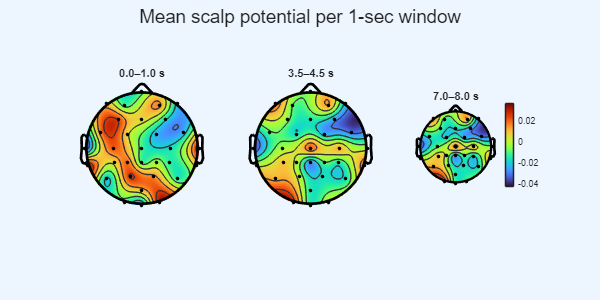


%% --- 1. Instantaneous (mean over 1-sec windows)
figure('Name','EEG scalp maps (time windows)','Color','w',...
    'Position',[100 100 500 200]);
for i = 1:n_maps
    t_start = map_times(i) - win_length/2;
    t_end   = map_times(i) + win_length/2;
    idx = EEG.times >= t_start*1000 & EEG.times < t_end*1000;
    data_avg = mean(EEG.data(:,idx),2);

    subplot(1,n_maps,i);
    topoplot(data_avg, EEG.chanlocs, 'maplimits', 'maxmin', 'electrodes', 'on');
    title(sprintf('%.1f–%.1f s', t_start, t_end));
end
sgtitle('Mean scalp potential per 1-sec window');
colorbar;


%% --- 2. Power topography (alpha band 8–12 Hz)
[psd, freqs] = spectopo(EEG.data, 0, EEG.srate, ...
    'chanlocs', EEG.chanlocs, 'freqrange', [1 60], 'plot', 'off');

Computing spectra (window length 512; fft length: 512; overlap 0):
................................


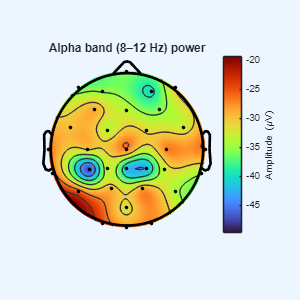



freqs = linspace(0, EEG.srate/2, size(psd,2));
alpha_idx = freqs >= 8 & freqs <= 12;
alpha_power = mean(psd(:,alpha_idx),2);

figure('Name','Alpha Power Topography','Color','w',...
    'Position',[100 100 300 300]);
topoplot(alpha_power, EEG.chanlocs, 'maplimits', 'maxmin', 'electrodes', 'on');
title('Alpha band (8–12 Hz) power');
cb = colorbar;
cb.Label.String = 'Amplitude (\muV)'; % or 'Power (dB)'

%% --- 3. Multiple maps at specific times (ERP-style)
figure('Name','ERP-style scalp sequence','Color','w',...
    'Position',[100 100 600 600]);
pop_topoplot(EEG, 1, map_times*1000, 'EEG-like Simulation', 0, 'maplimits', 'maxmin');

Plotting...


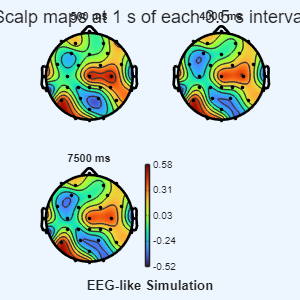

sgtitle('Scalp maps at 1 s of each 3.5 s interval');

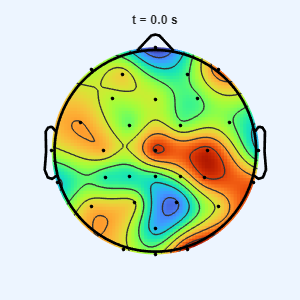


%% --- 4. Continuous animation (optional)
figure('Name','Animated scalp map','Color','w',...
    'Position',[100 100 300 300]);
for t_sec = 0:0.2:10   % every 200 ms
    clf;
    t_idx = dsearchn(EEG.times', t_sec*1000);
    topoplot(EEG.data(:,t_idx), EEG.chanlocs, 'maplimits', 'maxmin');
    title(sprintf('t = %.1f s', t_sec));
    drawnow;
end

function eeg_out = run_latent_to_eeg(Z, Fs, nChannels)
% run_latent_to_eeg  Map latent variables (3 x T) -> EEG-like signals (nChannels x T)
% - Simple frozen MLP with explicit weight matrices
% - Convolution with biphasic alpha-like kernel as output activation
% - Returns nChannels x T matrix

    rng(42); % reproducible frozen weights

    [nLatent, T] = size(Z);
    if nLatent ~= 3
        error('Z must be 3 x T (3 latents).');
    end

    %% MLP architecture
    hidden_sizes = [128, 64, 64]; % you can change to 2-3 hidden layers
    layer_sizes = [nLatent, hidden_sizes, nChannels];
    L = numel(layer_sizes)-1;

    % Initialize frozen weights and biases (Glorot uniform-ish)
    W = cell(L,1); b = cell(L,1);
    for li = 1:L
        fan_in = layer_sizes(li);
        fan_out = layer_sizes(li+1);
        lim = sqrt(6/(fan_in + fan_out));
        W{li} = ( -lim + (2*lim).*rand(fan_out, fan_in) ) * 0.8; % scale
        b{li} = zeros(fan_out,1);
    end

    % Forward pass (vectorized)
    A = Z; % size: features x T
    for li = 1:(L-1)
        Zlin = W{li} * A + b{li} * ones(1, T); % fan_out x T
        A = tanh(Zlin); % hidden activation
    end
    Ylin = W{L} * A + b{L} * ones(1, T); % nChannels x T (pre-output)

    % Spatial mixing (to create channel topographies)
    M = orthonormal_mix(nChannels, size(Ylin,1));
    Ymixed = M * Ylin; % nChannels x T

    % Ymixed = Ylin; % nChannels x T
    % Output activation: convolve with biphasic alpha-like kernel
    kernel = biphasic_alpha_kernel(Fs, 0.35); % 0.35 s kernel
    eeg_conv = zeros(size(Ymixed));
    for ch = 1:size(Ymixed,1)
        eeg_conv(ch,:) = conv(Ymixed(ch,:), kernel, 'same');
    end

    % mild pointwise nonlinearity and add small sensor noise
    eeg_nl = tanh(1.1 * eeg_conv);
    eeg_out = eeg_nl + 5e-3 * randn(size(eeg_nl));
end


## --- small helpers ----------------------------------------------------

function M = orthonormal_mix(rows, cols)
    % returns rows x cols mixing matrix with reasonable scaling
    A = randn(rows, cols);
    if rows >= cols
        [Q,~] = qr(A,0);
        M = Q(:,1:cols);
    else
        [Q,~] = qr(A',0);
        M = Q(1:rows, :)';
    end
    M = M .* (0.7 + 0.4*randn(size(M))); % add small amplitude variability
end

function K = biphasic_alpha_kernel(Fs, dur)
    % produce a biphasic alpha-like kernel (zero-mean, normalized)
    t = (0:1/Fs:dur)';
    tau1 = 0.06; amp1 = 1.0;
    tau2 = 0.12; amp2 = 0.8;
    g1 = (t./tau1) .* exp(1 - t./tau1);
    g2 = (t./tau2) .* exp(1 - t./tau2);
    Kraw = amp1*g1 - amp2*g2;
    K = Kraw - mean(Kraw);
    K = K / max(abs(K) + eps);
end